# 演習9-1 ベクトルノルム計算

•ベクトルbを定義し，ノルムを計算しなさい



$$b=\left\lbrack \begin{array}{ccc}
3 & 4 & 5
\end{array}\right\rbrack$$


b=[3 4 5];
%　1-ノルム
norm(b, 1)

ans =     12.0000e+000


%　2-ノルム
norm(b, 2)

ans =      7.0711e+000


%　∞-ノルム
norm(b, 'inf')

ans =      5.0000e+000


# 演習9-3 行列ノルム計算

•行列Aを定義し，1-ノルム, 2-ノルム,∞-ノルムと条件数を計算しなさい


$$A=\left\lbrack \begin{array}{ccc}
2 & 3 & 4\\
1 & 2 & 3\\
1 & 1 & 3
\end{array}\right\rbrack$$



A=[2 3 4;1 2 3;1 1 3];
%　1-ノルム
norm(A, 1)

ans =     10.0000e+000


%　2-ノルム
norm(A, 2)

ans =      7.2894e+000


%　∞-ノルム
norm(A, 'inf')

ans =      9.0000e+000


%　条件数
cond(A)

ans =     23.2528e+000


# 演習9-4 悪条件の線形方程式 

•２つの線形方程式を定義して解く



$$Ax_1 =b_1 ,Ax_2 =b_2$$



$$A=\left\lbrack \begin{array}{cc}
1 & 0\ldotp 1001\\
10 & 1
\end{array}\right\rbrack ,b_1 =\left\lbrack \begin{array}{c}
1\ldotp 1001\\
11
\end{array}\right\rbrack ,b_2 =\left\lbrack \begin{array}{c}
1\ldotp 1\\
11
\end{array}\right\rbrack$$


•係数行列の条件数cond(A)を計算：約100000


% 係数行列と右辺ベクトルの定義
A=[4 2 0 0 0;5 0 1 0 0;2 6 2 2 3;2 2 5 5 6];
b1=[3;11;-4;12];
b2=[1.1;11];
% 行列の条件数を計算しなさい
cond(A)

ans =     29.6685e+000


% 2つの線形方程式を解きなさい
A\b1

ans =      1.8462e+000
    -2.1923e+000
     1.7692e+000
     0.0000e+000
   641.0256e-003


%A\b2

# 参考　ヒルベルト行列の条件数

•悪条件の行列であるヒルベルト行列の条件数を計算する

•10次元の行列で条件数が1.60e+13に達する

dim=[2 5 10];
% ヒルベルト行列の定義
for k=1:size(dim,2)
  n=dim(k)
clear A
for i=1:n
  for j=1:n
    A(i,j)=1/(i+j-1);
  end
end
cond(A)
end

n =      2.0000e+000


ans =     19.2815e+000


n =      5.0000e+000


ans =    476.6073e+003


n =     10.0000e+000


ans =     16.0249e+012


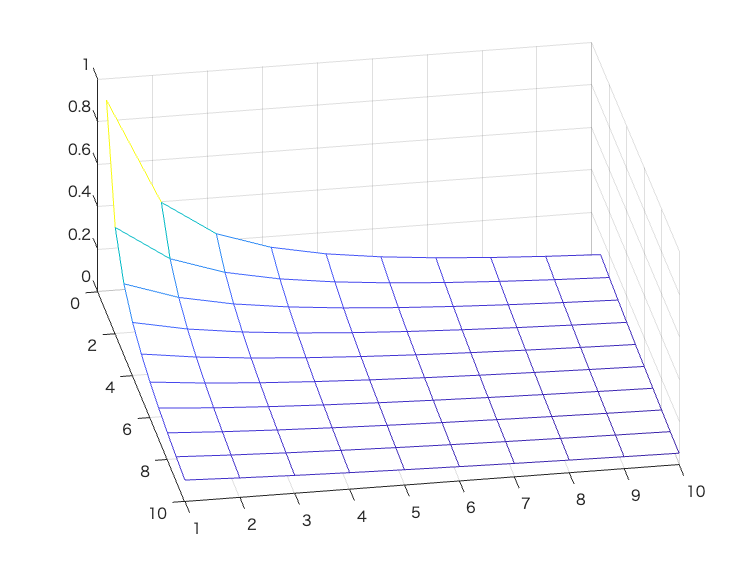

mesh(A);
view([80,45]);